# Unidad 6 - TP #8a

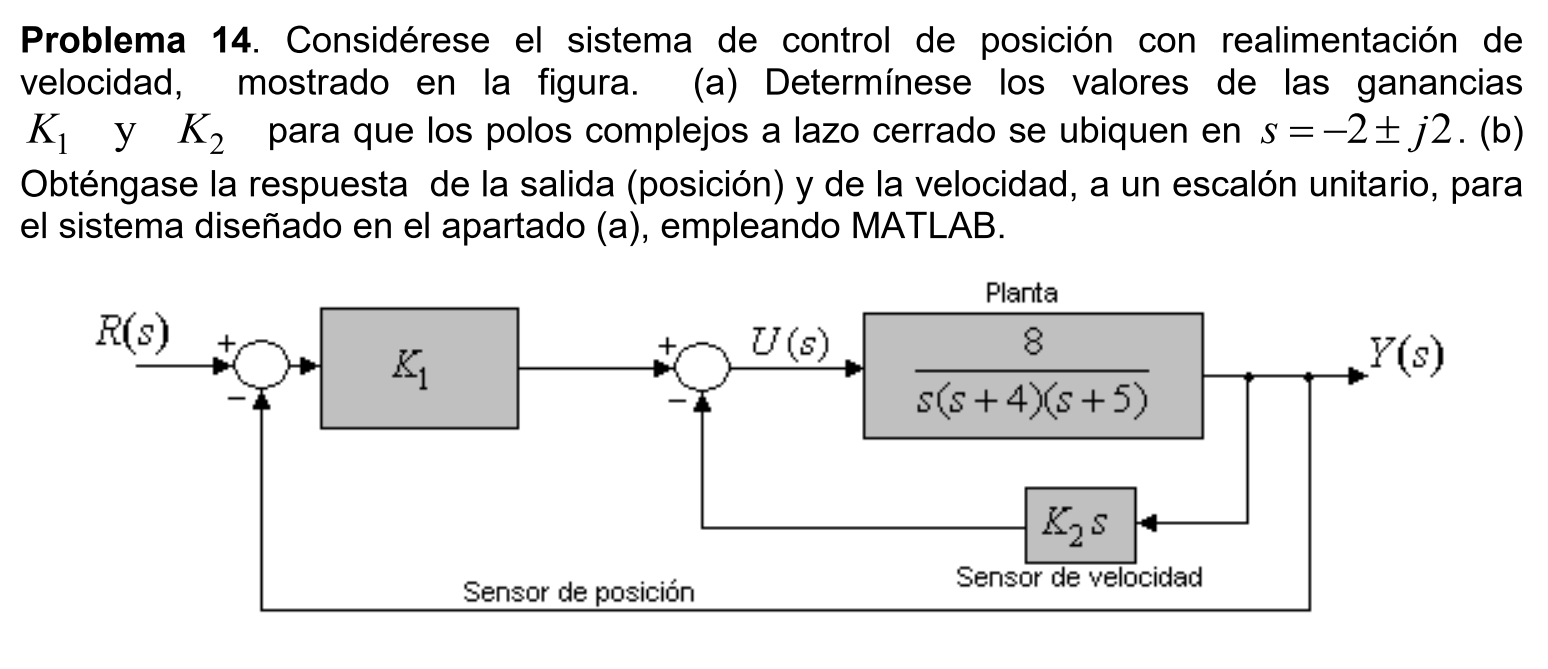

## Analizamos nuestro sistema.


$$\begin{array}{l}
G_1 \left(s\right)=k_1 \\
G_2 \left(s\right)=\frac{8}{s\left(s+4\right)\left(s+5\right)}\\
H_1 \left(s\right)=1\\
H_2 \left(s\right)=s\;k_2 
\end{array}$$



$$\begin{array}{l}
M_{\mathrm{int}} \left(s\right)=\frac{G_2 \left(s\right)}{1+G_2 \left(s\right)H_2 \left(s\right)}\\
M\left(s\right)=\frac{G_1 \left(s\right)M_{\mathrm{int}} \left(s\right)}{1+G_1 \left(s\right)M_{\mathrm{int}} \left(s\right)H_1 \left(s\right)},M\left(s\right)=\frac{G_1 \left(s\right)\frac{G_2 \left(s\right)}{1+G_2 \left(s\right)H_2 \left(s\right)}}{1+G_1 \left(s\right)\frac{G_2 \left(s\right)}{1+G_2 \left(s\right)H_2 \left(s\right)}H_1 \left(s\right)},\\
M\left(s\right)=\frac{\left(\frac{{G_1 \left(s\right)G}_2 \left(s\right)}{1+G_2 \left(s\right)H_2 \left(s\right)}\right)\;\left(1+G_2 \left(s\right)H_2 \left(s\right)\right)}{1+G_2 \left(s\right)H_2 \left(s\right)+G_1 \left(s\right)G_2 \left(s\right)},\;M\left(s\right)=\frac{G_1 \left(s\right)G_2 \left(s\right)}{1+G_2 \left(s\right)H_2 \left(s\right)+G_1 \left(s\right)G_2 \left(s\right)},\\
M\left(s\right)=\frac{\frac{8k_1 }{s\left(s+4\right)\left(s+5\right)}}{1+\frac{s\;8k_2 }{s\left(s+4\right)\left(s+5\right)}+\frac{8k_1 }{s\left(s+4\right)\left(s+5\right)}},M\left(s\right)=\frac{8k_1 }{s\left(s+4\right)\left(s+5\right)+s\;8k_2 +8k_1 },\\
M\left(s\right)=\frac{8k_1 }{s\left(s^2 +s\;9+20\right)+s\;8k_2 +8k_1 },\\
M\left(s\right)=\frac{8k_1 }{s^3 +s^2 9+s\left(20+8k_2 \right)+8k_1 }
\end{array}$$


Del enunciado podemos obtener la posición de 2 polos complejos y conjugados en -2 ± j2 y un polo real, por lo tanto

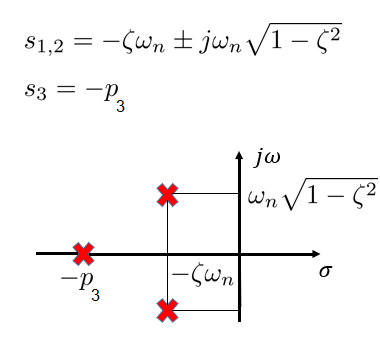

Entonces,


$$\left(s-p_1 \right)\left(s-p_2 \right)\left(s-p_3 \right)=\left(s+2+\mathrm{j2}\right)\left(s+2-\mathrm{j2}\right)\left(s+p_3 \right)$$


Analizando solo los polos complejos,


$$\left(s-p_1 \right)\left(s-p_2 \right)=\left(s+2+\mathrm{j2}\right)\left(s+2-\mathrm{j2}\right),\left(s-p_1 \right)\left(s-p_2 \right)=s^2 +s\;4+8$$


Por lo tanto,


$$\begin{array}{l}
\left(s^2 +s\;4+8\right)\left(s+p_3 \right)=s^3 +s^2 9+s\left(20+8k_2 \right)+8k_1 \\
s^3 +s^2 \left(4+p_3 \right)+s\left(8+4p_3 \right)+8p_3 =s^3 +s^2 9+s\left(20+8k_2 \right)+8k_1 
\end{array}$$


Donde,

- 
$$4+p_3 =9$$


- 
$$8+4p_3 =20+8k_2$$


- 
$$8p_3 =8k_1$$


Obteniendo,

- 
$$p_3 =5$$


- 
$$k_2 =1$$


- 
$$k_1 =5$$


Por lo que nuestra transferencia a lazo cerrado queda como,


$$M\left(s\right)=\frac{40}{s^3 +s^2 \;9+s\;28+40}$$


close all;
clear;
clc;

s = tf('s');

G1 = 5;
G2 = 8/(s*(s+4)*(s+5));
H1 = 1;
H2 = s;

M_int = feedback(G2,H2);
M = feedback(G1*M_int, H1);

disp('Los polos de nuestro sistema estan en:');

Los polos de nuestro sistema estan en:


p = pole(M)

p =   -5.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 2.0000i


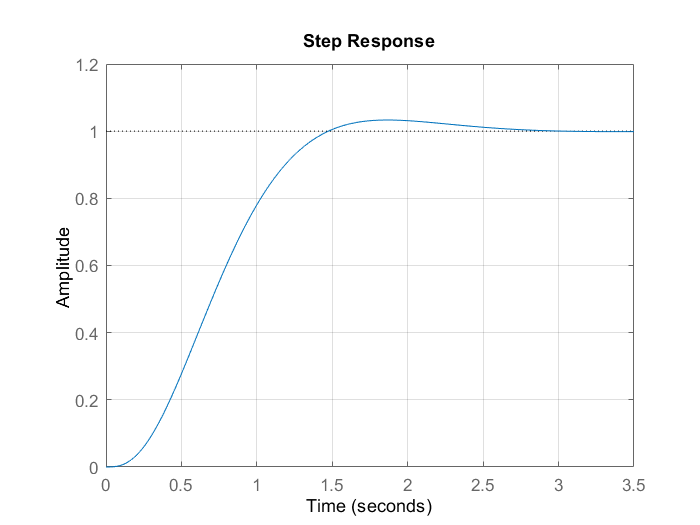


step(M);
grid on;

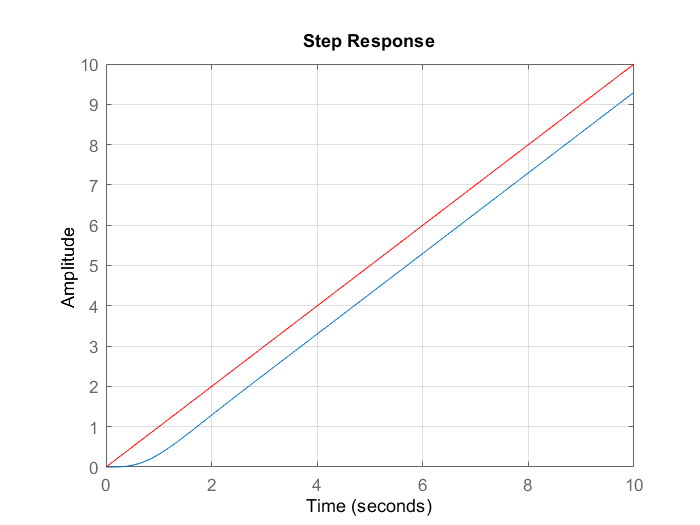


figure;
t = 0:0.1:10;
ramp = t;
step(M/s);
hold on;
plot(t,ramp, 'r');
grid on;
xlim([0 10]);